# Doc: Assess local tuning biases in the mouse dLGN

- perhaps add something that is not the title of your paper, maybe the goal of the paper, or the significance sttament

- link abstract or complete manuscript/thesis

TO DO

- finalize rank sum test code

- add discussion and some references

- convert to mark down

## Overview

The aim of the project is to assess the presence of 'local tuning biases' among populations of LGN afferents innervating the mouse primary visual cortex. From a computer vision point of view, we test the notion that neurons/units in the dLGN 'process' image regions with a similar, or biased, set of orientated filters. 

To answer this question,  

- We estimate the spatial receptive fields and oriention tuning of populations of thalamic boutons innervating mouse V1. 

- Then for each pair of boutons, determing the extent to which their receptive fields overlap and the similarity of their tuning profiles

If LGN boutons with overlapping receptive fields have similar tuning profiles, this would suggest the presence of local tuning biases.

# Methods

## Data collection 

We expressed GcaMP6s in dLGN boutons innervating L2/3 and L4 of mouse primary visual cortex and measured their visual properties using resonant, two-photon microscopy in the awake, behaving mouse (**Figure ****13**). A total of three mice were used in this study. We imaged **[9]** unique cortical fields to obtain the data discussed here.

## Kernel Estimation

A bouton’s joint tuning to orientation and spatial frequency was measured by presenting a sequence of flashed, high-contrast sinusoidal gratings having pseudorandom orientations and spatial frequencies (Figure 13). We estimated the tuning of each bouton by linearly regressing its response on the grating stimulus and denote the estimated tuning kernel of the ith bouton in an imaging field by H_T^i. The peak of the tuning kernel also yielded a spatial frequency preference ω_i and an orientation preference θ_i for each bouton (see methods, Figure 13). 

We also measured the spatial receptive field maps of boutons by presenting a sequence of flickering, elongated bars at random orientations and positions across the visual field (Figure 13). A boutons RF map was estimated by correlating its response and the location of the bars. We denote the RF map corresponding to the ith bouton in an imaging field by H_R^i. 

## Image Processing

We then process each imaging dataset first by aligning the calcium images to correct for motion artifacts. Following motion stabilization, we segmented **regions of interest  (ROIS) **manually. These regions corresponded micrometer-sized circular or elliptical boutons of dLGN axons. Following segmentation, we extracted signals by computing the mean of the calcium fluorescence within each region of interest and discounting the signals from the nearby neuropil. Spikes were then estimated via deconvolution.

## Loading Properties of Boutons/ROIs

To being the the analysis, we need to first get the tuning kernels and receptive of boutons. To do this we load the ROI data table. In this table Rows correspond to a lgn bouton in some imaging field and columns correspond some property of that bouton. *Here are some of these properties...*

tuning properties

- kern_tun is the tuning kernel of bouton, which represents its response to the joint spatial frequency and orientation of a grating

- oriest is the orientation preference of the bouton/roi

- osi is the orientation selectivity of the bouton

- sfPeak is the peak spatial frequency preferences of the bouton

- signifi_tun represesents whethere or not (1 or 0) the boutons's tuning kernel is  'significant'. That is, some boutons have tuning kernels are too noisy. only play with those that are clean and crisp.

properties of the bouton's receptive fields

- kern_ret is the spatial receptive field map/kernel of the bouton, which represents its response to different regions of visual space

- signifi_ret represesents whethere or not (1 or 0) the boutons's spatial receptive field imap/kernel os  'significant'. That is, some boutons have receptive fields maps that are too noisy. Only play with those that are clean and crisp. 

## *Getting the Table...*

% Initialze
clear;
clc;
addpath /Users/luis/Box/prjLGNTB/lgnDATA/   
addpath /Users/luis/Box/prjLGNTB/lgnANALYSIS/
cd /Users/luis/Box/prjLGNTB/lgnANALYSIS
lgn = lgnanz;

Select your imaging fields of boutons  (there are 9 total)

% lgn.all_available_uif'
uifs_to_process = lgn.all_available_uif([1,2])

Generate the roi table.

lgn.get_roi_tables(uifs_to_process);

ans =      1
     2


Make sure the imaging fields you wanted are actually in the table....

lgn.roi_stack_uif_list % here are all the imaging fields in the roi table

ans = 8×22 table
    masterEntry    entryNumber      mouse      uniqImFieldNum    hasRetData    hasTunData    roi_ID_Ret    roi_ID_Tun        kern_ret         kurt_ret        sig_ret            xy_ret       kern_tun    signif_tun    sig_tun      oricurve       oriest       sfcurve       osi    sfPeak    segment_xy_tun    segment_area_tun
    ___________    ___________    _________    ______________    __________    __________    __________    __________    _________________

Lets look at the table

head(lgn.roi_stack) 

ans = 8×22 table
    masterEntry    entryNumber      mouse      uniqImFieldNum    hasRetData    hasTunData    roi_ID_Ret    roi_ID_Tun        kern_ret         kurt_ret        sig_ret            xy_ret          kern_tun       signif_tun        sig_tun           oricurve            oriest            sfcurve              osi                  sfPeak                     segment_xy_tun               segment_area_tun
    ___________    ___________    _________    ______________    __________    __________    _________

tail(lgn.roi_stack)

**Check out some of the properties of the rois.**

lgn.roi_stack.Properties.VariableNames

ans = 1×22 cell array
  Columns 1 through 4
    {'masterEntry'}    {'entryNumber'}    {'mouse'}    {'uniqImFieldNum'}
  Columns 5 through 8
    {'hasRetData'}    {'hasTunData'}    {'roi_ID_Ret'}    {'roi_ID_Tun'}
  Columns 9 through 13
    {'kern_ret'}    {'kurt_ret'}    {'sig_ret'}    {'xy_ret'}    {'kern_tun'}
  Columns 14 through 18
    {'signif_tun'}    {'sig_tun'}    {'oricurve'}    {'oriest'}    {'sfcurve'}
  Columns 19 through 22
    {'osi'}    {'sfPeak'}    {'segment_xy_tun'}    {'segment_area_tun'}

`Note that some rois/boutons have a tuning kernels AND a receptive field, while some have only one but not the other. This analysis only considers boutons with BOTH types of kernels`

## You can plot a histogram of any proprety 

ans =      1     2


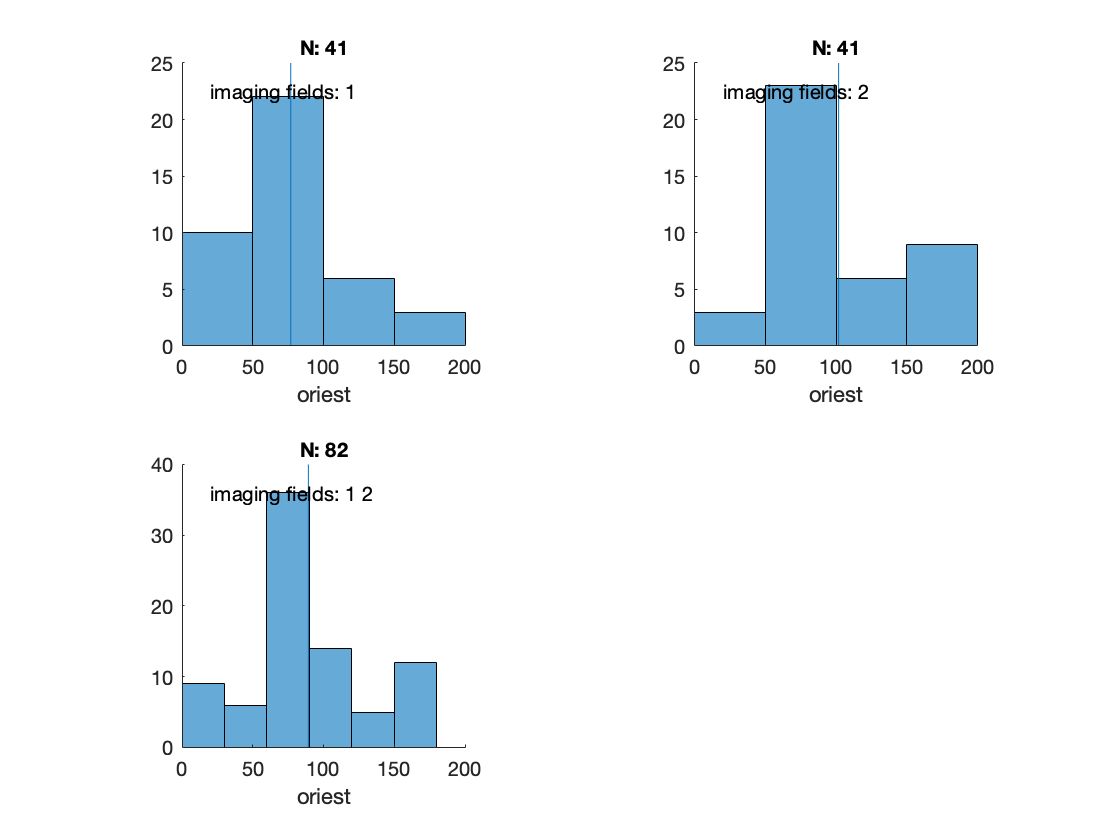

ans = 8×33 table
      mouse      uif    pair_roiDistMatIdx    pair_roiOrisfId    pair_roiHoughId    dRetKern_c2cDist    dRetKern_corr    dRetKern_corrStrong    dRetKern_corrWeak     dRetKern_Overlap     dRetKern_OverlapFiftyPrc    dRetKern_OverlapYes    dRetKern_OverlapNo      dTunKern_cos         dTunKern_corr            dSfResp              dLogSfEst         dLogSfEst_lessThanHalfOct    dLogSfEst_lessThanOneOct    dLogSfEst_lessThanTwoOct    dLogSfEst_lessThanThreeOct    dLogSfEst_AnyDiff    dLogSfEst_moreThanHalfOct    dLogSfEst_moreThanOneOct    dLogSfEst_moreThanTwoOct

ans = 8×33 table
      mouse      uif    pair_roiDistMatIdx    pair_roiOrisfId    pair_roiHoughId    dRetKern_c2cDist     dRetKern_corr    dRetKern_corrStrong    dRetKern_corrWeak     dRetKern_Overlap     dRetKern_OverlapFiftyPrc    dRetKern_OverlapYes    dRetKern_OverlapNo      dTunKern_cos         dTunKern_corr            dSfResp              dLogSfEst         dLogSfEst_lessThanHalfOct    dLogSfEst_lessThanOneOct    dLogSfEst_lessThanTwoOct    dLogSfEst_lessThanThreeOct    dLogSfEst_AnyDiff    dLogSfEst_moreThanHalfOct    dLogSfEst_moreThanOneOct    dLogSfEst_moreThanTwoOct</

close all

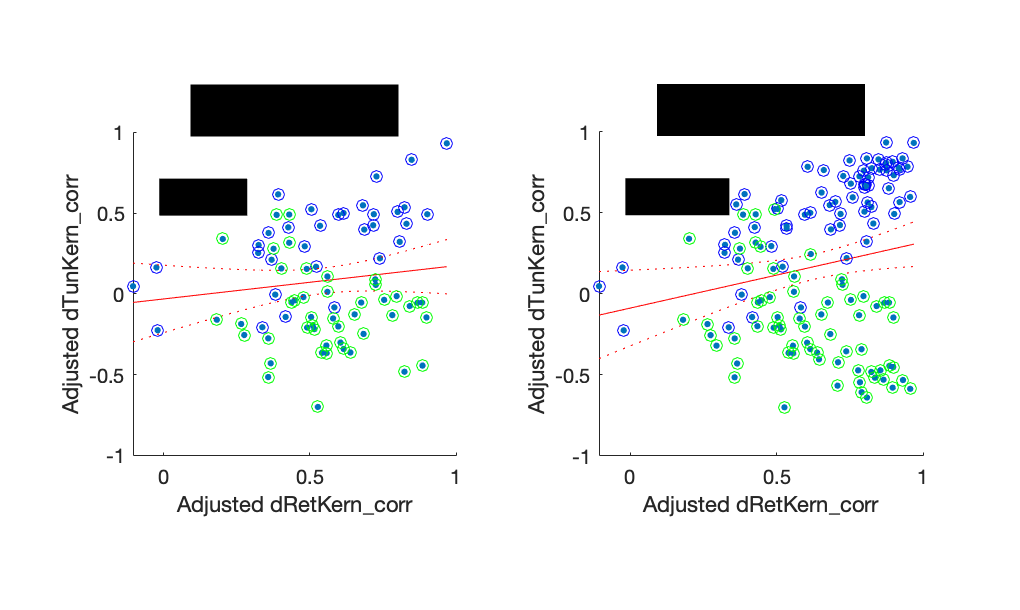

variable_name = 'oriest';
main_requirement = logical(lgn.roi_stack.signif_tun);

uif1_roi_requirments = lgn.roi_stack.uniqImFieldNum == 1 & main_requirement;
tbl_uif1_of_single_rois = lgn.roi_stack(uif1_roi_requirments,:);
lgn.plot_univar_hist(tbl_uif1_of_single_rois, variable_name)

uif2_roi_requirments = lgn.roi_stack.uniqImFieldNum == 2 & main_requirement;
tbl_uif2_of_single_rois = lgn.roi_stack(uif2_roi_requirments,:);

lgn.plot_univar_hist(tbl_uif2_of_single_rois, variable_name)

uifALL_roi_requirments = main_requirement;
tbl_uifALL_of_single_rois = lgn.roi_stack(main_requirement,:);
lgn.plot_univar_hist(tbl_uifALL_of_single_rois, variable_name)


Note that dLGN boutons innervating mouse primary visual cortex have preferred orientations has a bias for cardinal orientations. This is similar to the results of Sun et al 2016.

# Main Analysis

Recall that the goal is to determine if LGN boutons with overlapping receptive fields have similar tuning profiles. This would suggest  that neurons/units in the dLGN 'process' image regions with a similar, or biased, set of orientated filters. 

To do test this we take each possible pair of boutons (i,j)  in an imaging field, then compute the overlap between their receptive fields, and then compute the similarity of their tuning profiles. We define the tuning similarity of bouton pairs as the as the correlation between their joint tuning kernels  . The RF overlap of bouton pairs is defined as the correlation coefficient between their RF maps

To get these pair-wise distant measures between boutons, we load the distance table. Each row  of the table corresponds to a pair of LGN boutons in some imaging field, and the columns correspond to some property of that bouton pair. We are most interestied in the receptive field overlap and tuning similarity of boutons pairs.

## How to get the distance Table

Again look at available data table of rois

lgn.roi_stack_uif_list'

Load the distance table

lgn.get_distance_table(); 

Take a look at it.

head(lgn.dist_stack)    

tail(lgn.dist_stack)

## Model the relationship between tuning similarity and RF overlap, for pairs of boutons in one imaging field

Now that we have a data table of pairs, plot the relationship between tuning similarity and receptive field overlap...

clf;
uif  = lgn.roi_stack_uif_list(1);
lgn.fit_plot_lm(uif);

Run it again but this time with all pairs of boutons, accross all imaging fields

uif_stack   = lgn.roi_stack_uif_list;
lgn.fit_plot_lm(uif_stack);

## Run a Rank Sum Test (Building)

## Discussion